## 重建反投影算法

2021级物理学（拔尖计划） 房业齐

首先生成一个头部模型，用来作为本次计算的图片

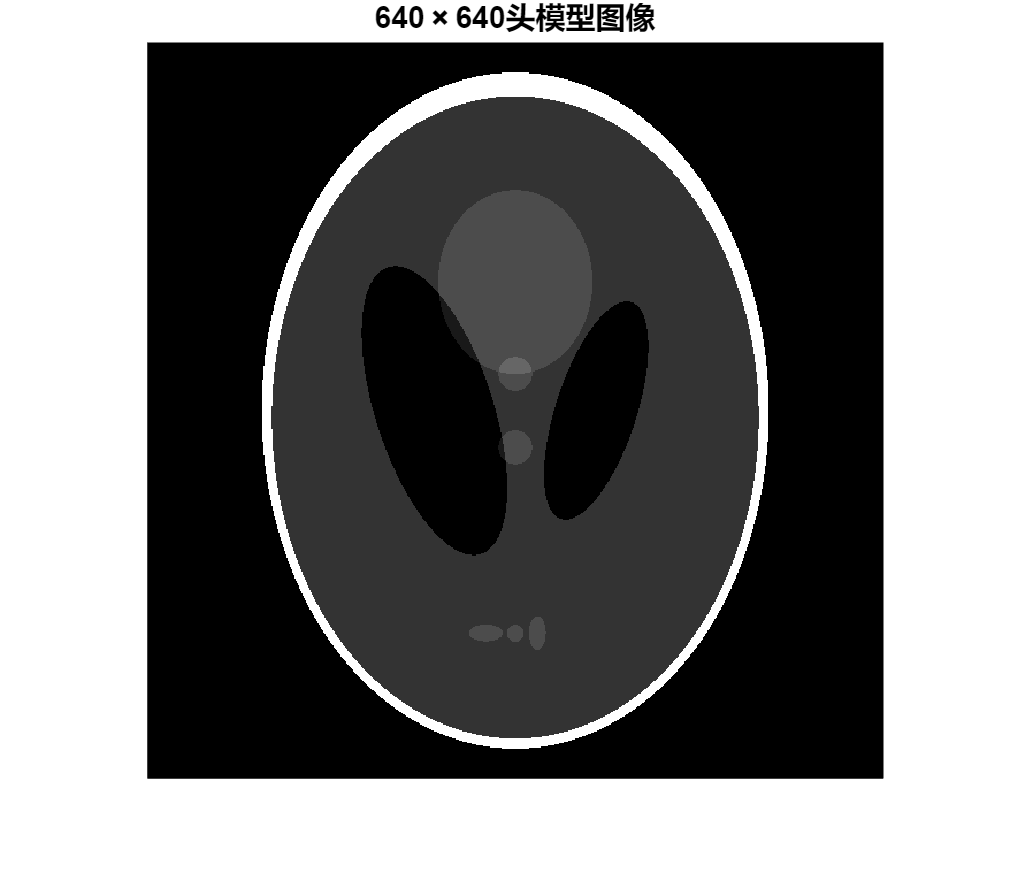

I=phantom(640);
theta=0:179;
P=radon(I,theta);
figure;
imshow(I,[]),title('640\times640头模型图像');

### 进行Redon变换

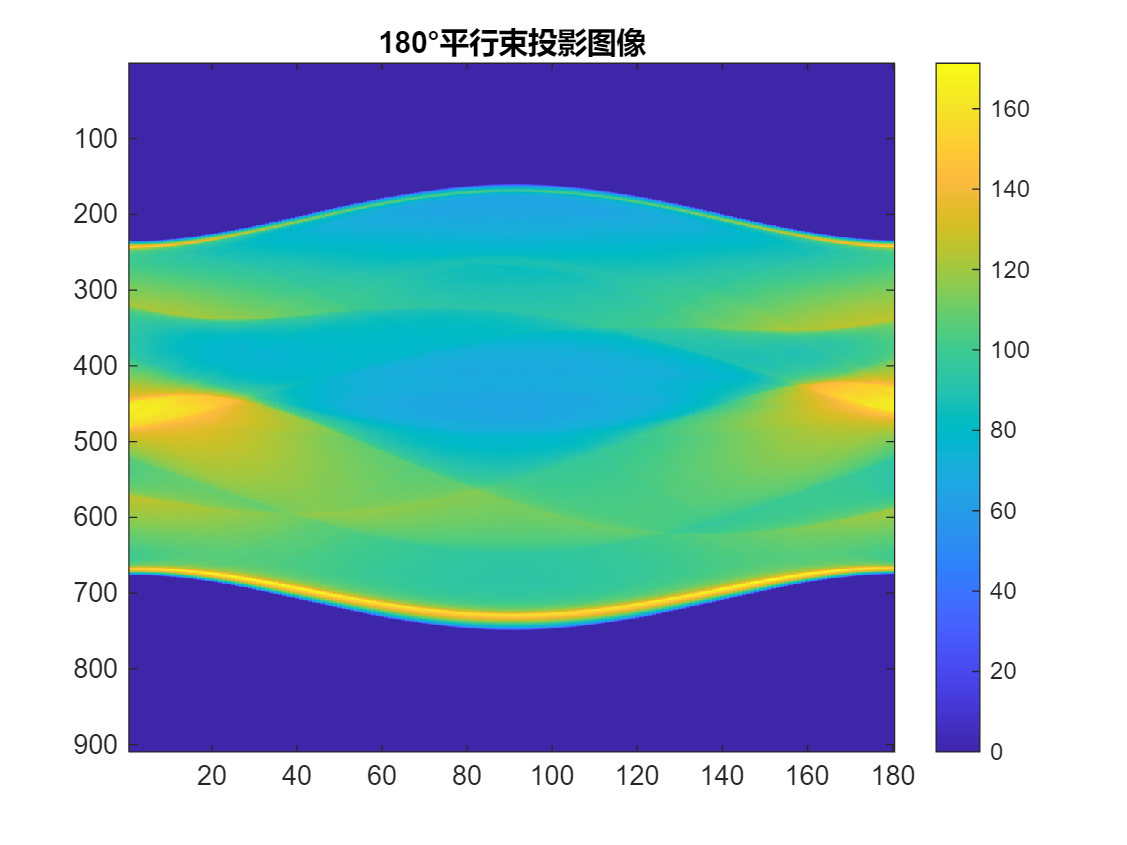

figure;
imagesc(P),colormap("default"),colorbar,title('180°平行束投影图像');

### 对比四种不同而重建算法

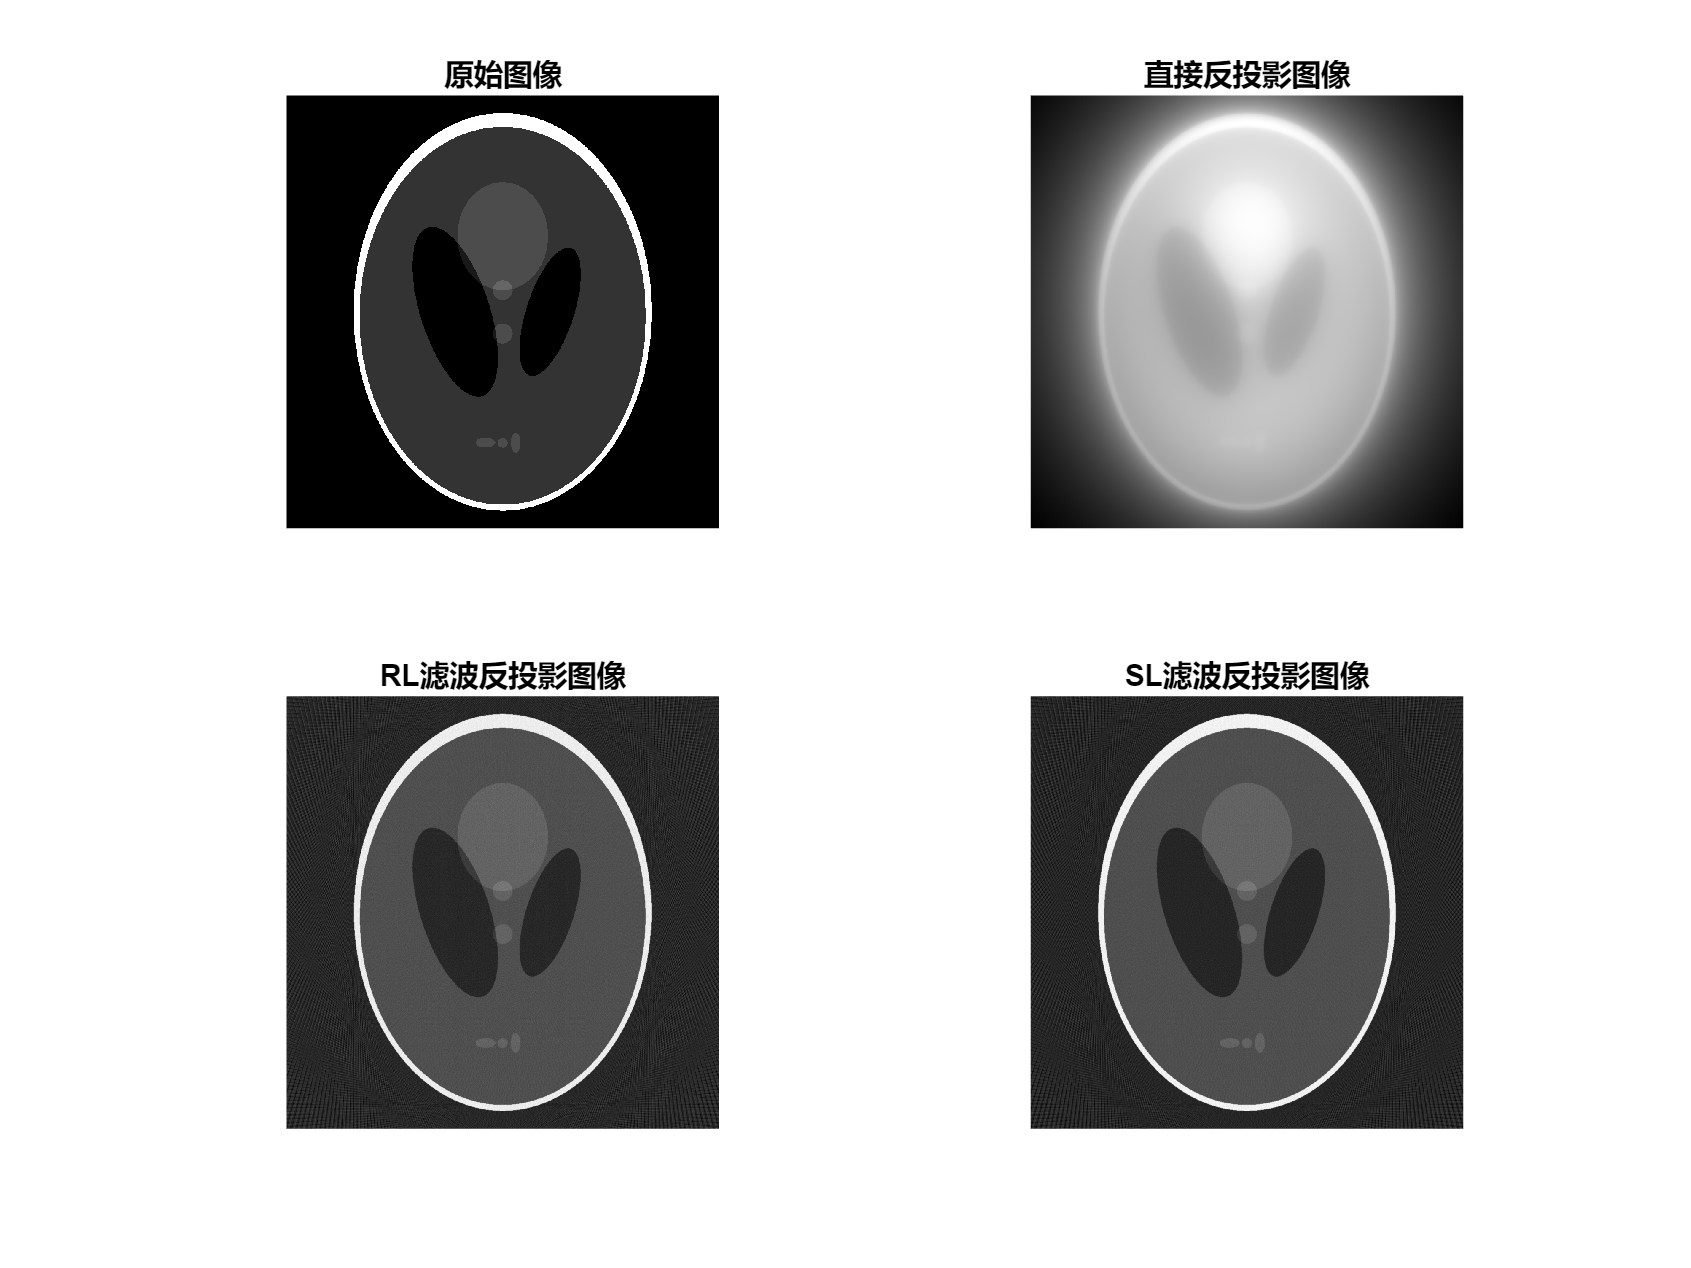

I=phantom(1024);
theta=0:1:179;
P=radon(I,theta);
rec=iradon(P,theta,'linear','None');
rec_RL=iradon(P,theta,'Ram-Lak');
rec_SL=iradon(P,theta,'linear','Shepp-Logan');
f = figure;
subplot(2,2,1);imshow(I,[]),title('原始图像');
subplot(2,2,2);imshow(rec,[]),title('直接反投影图像');
subplot(2,2,3);imshow(rec_RL,[]),title('RL滤波反投影图像');
subplot(2,2,4);imshow(rec_SL,[]),title('SL滤波反投影图像');
f.Position(3:4) = 1.5 * f.Position(3:4);